data = readtable('mysticdata.csv','Delimiter',';','VariableNamingRule',"preserve");
disp("The column names are: ")

The column names are: 


disp(data.Properties.VariableNames)  

    {'t'}    {'x'}    {'y'}    {'z'}




% extract variables
x = data.x;
y = data.y;
z = data.z;
t = data.t;

dissimilarities1 = pdist(data{1:end,2:end}, "euclidean"); % compute pairwise Euclidean distances
% nonlinear MDS
[Y1,stress1,disparities1] = mdscale(dissimilarities1, 2,'criterion','stress','Options',statset('MaxIter', 1000, 'TolFun',1e-9));
distances1 = pdist(Y1);

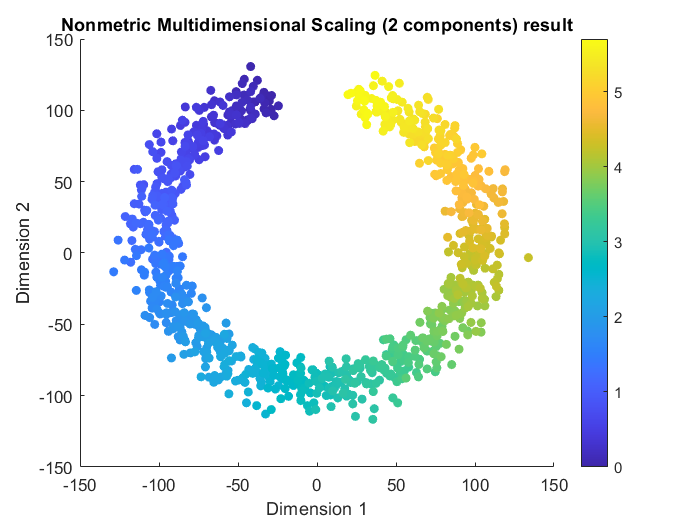

% Create a scatter plot with the three cities highlighted in red, green, and yellow, respectively
figure;
scatter(Y1(:,1), Y1(:,2), 30, t, 'filled');
xlabel('Dimension 1');
ylabel('Dimension 2');
title('Nonmetric Multidimensional Scaling (2 components) result');
colorbar;

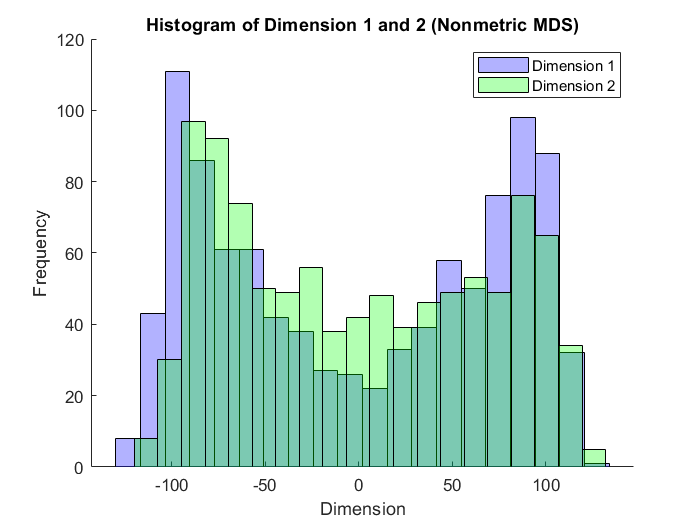

figure;
hold on;
histogram(Y1(:,1),20,'FaceAlpha',0.3,'FaceColor','blue');
histogram(Y1(:,2),20,'FaceAlpha',0.3,'FaceColor','green');
xlabel('Dimension');
ylabel('Frequency');
title('Histogram of Dimension 1 and 2 (Nonmetric MDS)');
legend('Dimension 1', 'Dimension 2');

dissimilarities2 = pdist(data{1:end,2:end}, "euclidean"); % compute pairwise Euclidean distances
% nonlinear MDS
[Y2,stress2,disparities2] = mdscale(dissimilarities2, 2,'criterion','sammon','Options',statset('MaxIter', 1000, 'TolFun',1e-9));
distances2 = pdist(Y2);

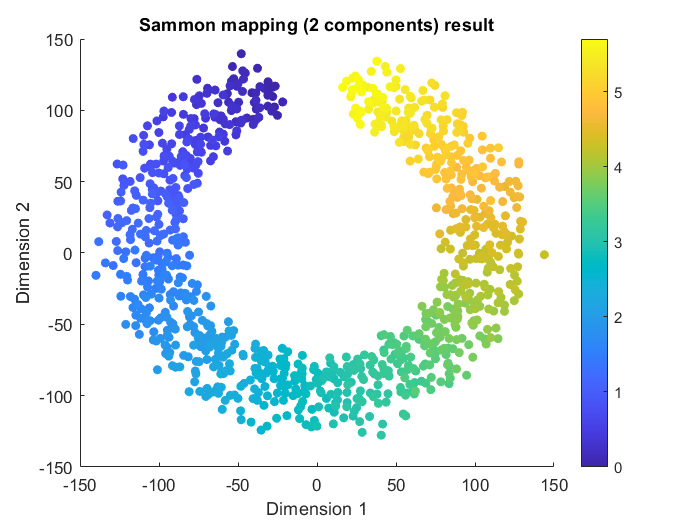

% Create a scatter plot with the three cities highlighted in red, green, and yellow, respectively
figure;
scatter(Y2(:,1), Y2(:,2), 30, t, 'filled');
xlabel('Dimension 1');
ylabel('Dimension 2');
title('Sammon mapping (2 components) result');
colorbar;

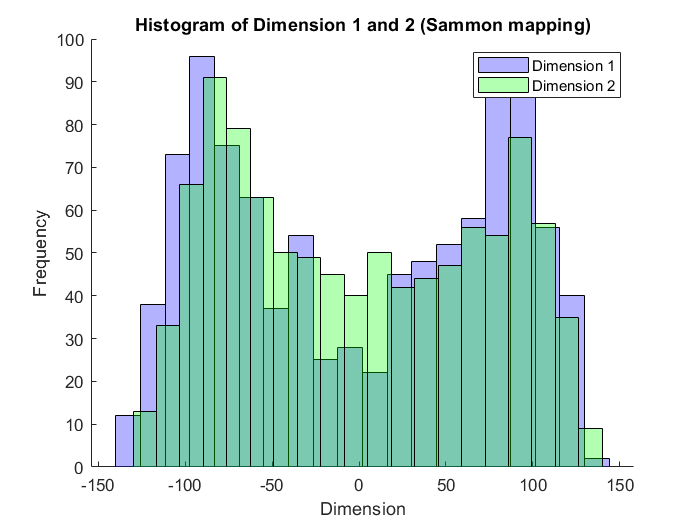

figure;
hold on;
histogram(Y2(:,1),20,'FaceAlpha',0.3,'FaceColor','blue');
histogram(Y2(:,2),20,'FaceAlpha',0.3,'FaceColor','green');
xlabel('Dimension');
ylabel('Frequency');
title('Histogram of Dimension 1 and 2 (Sammon mapping)');
legend('Dimension 1', 'Dimension 2');